**SINGULAR VALUE DECOMPOSITION - SVD **

1. Create a 2x3 matrix with rank 2 

A = randi(10,2,2) * randi(10,2,3);
fprintf("Rank of A is: %d", rank(A));

2. Create a 4x4 matrix with rank 1

B = randi(5,4,1) * randi(5,1,4);
fprintf("Rank of B is: %d",rank(B));

3. Create a 3x3 matrix with rank 2.  Find its eigen vectors. Show that eigenvectors corresponding to non-zero eigen values lies in column space

% Generate a matrix 3x3 with rank 2
C = randi(5,3,2) * randi(5,2,3);
fprintf("Rank of C is: %d",rank(C));

% Compute [eigenvector, eigenvalue] of C
[e_vec, e_val] = eig(C)

x =     0.0258
    1.6516
    0.6193
   -0.2967



% To check whether eigen vectors belong to the columnspace of C, 
% append the e_vec one by one to C and check rank
vec1 = e_vec(:,1)
C1 = [C vec1]
fprintf("Rank of C1 is: %d",rank(C1));

% append as row to further make sure it is not from row space 
C2 = [C; vec1']
fprintf("Rank of C2 is: %d",rank(C2));

4. Find the complete solution to the following system.  

 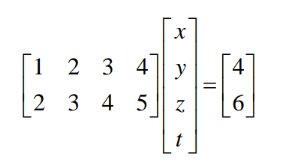

% Generate matrix A and b
A = [1 2 3 4; 2 3 4 5];
b = [4; 6];

% Find the solution
xp = pinv(A)*b;

xn = null(A)*randi(9, size(null(A),2),1);

x = xp + xn

5. Using SVD, find basis set for all the spaces associated with a matrix

% Generate a random matrix 
A = randi(5,4,2);
A = [A A*randi(5,2,2)]
r = rank(A);
fprintf("Rank of A is: %d",r);

% Compute the SVD
[U,S,V]=svd(A);

% Basis for columnspace
CS = U (:, 1:r)
% Check
rank([A CS])

% Basis for Left nullspace
LNS = U(:,r+1:end)
% check x'*A = 0
LNS' * A

V=V';

% Basis for rowspace
RS = V (1:r,:)
% Check
rank([A; RS])

% Basis for Right nullspace
RNS = V(r+1:end,:)
% check A*x = 0
A*RNS'

6. Generate a matrix 4x4 of rank 2. Find SVD, singular values, A'A and AA'. their eigen values.  Connect the relation

% Generate a matrix 4x4 of rank 2
A = randi(5,4,2) * randi(5,2,4);
fprintf("Rank of A is: %d",rank(A));

% Generate SVD
[U,S,V] = svd(A)

% Find singular values
sv = [];
for i = 1:4
    sv = [sv; S(i,i)];
end
disp(sv);

% Generate A'A and AA' and their eigen values
ATA = A'*A;
AAT = A*A';

eig(ATA)
eig(AAT)

disp("Relation: Eigen values of ATA and AAT are same. ");

7. Create a system of quations Ax=b such that b is not in the column space of A and hence no solution.  Using pseudo incerse obtain the least square 

% Generate A
A = [ 1 2; 3 4; 5 6]

% Generate a random b 
b = [ 1; 1; 1]

disp("Since b is not in the columnspace of A, the system of equations have no solution.");

% Compute psuedoinverse 
Ainv = pinv(A);

% Obtain the least square solution 
x_tilde= Ainv * b

9. Create a random 5x4 matrix A with rank 2 and a 5x1 vector b such that Ax=b has infinite solution

% Generate a 5x4 matrix A 
A = randi(5,5,2) * randi(5,2,4)

% Generate a 5x1 vector b that lies in the columnspace of A
b = sum(A,2)

% Generate least norm solution 
x = pinv(A) * b

% Generate infinite many solutions 
xs=[];
for i = 1:3
    x = (pinv(A) * b) + (null(A)*randi(5,2,1)); % xp + xn
    A*x % check 
    xs = [xs x];
end
disp("Infinitely many solutions: ");
disp(xs);

APPLICATION 1: IMAGE WATERMARKING

clc
%this is a color image
cover_image = imread("sky.jpg");  
%converting a color image to grayscale
cover_image_g = rgb2gray(cover_image); 
%convert the type to double
cover_image_g_ = im2double(cover_image_g);
% to resize the image to our desired dimension
cover_image_g_resized = imresize(cover_image_g_,[600,600]); 
% display cover image
figure;imshow(cover_image_g_resized);title("Cover image");

%same followed for watermarked image
watermark_image = imresize(im2double(rgb2gray(imread("yelflower.jpg"))),[600,600]);
figure;imshow(watermark_image); title("Image to be watarmarked")

% STEP 1 - Find SVD of cover image
[U, Sc, V]=svd(cover_image_g_resized);
alpha = 0.001;

% STEP 2 - watermark embedding 
Sn=Sc+(alpha*watermark_image);

% STEP 3 - define the watermark image 
watermarked_image = U*Sn*V';

% display the image 
figure;imshow(watermarked_image); title("watermarked image");

% STEP 4 - extract the original image
extracted_image = (1/alpha) * (Sn-Sc);

%display the image
figure; imshow(extracted_image); title("Extracted image");

APPLICATION 2: IMAGE COMPRESSION 

% Import the original image using imread
original_image = imread('sky.jpg');
original_image = rgb2gray(original_image);

% DISPLAY THE ORIGINAL IMAGE
figure;
subplot(1, 2, 1);
imshow(original_image);
title('Original Image');

% Generate SVD
[U, S, V] = svd(double(original_image));

% Compute the compression ratio 
compression_ratio = 1000/min(size(S)); % size(s) - [row col]; 
                                      % min - smallest el in the vector

% Number of singular values to be taken
num_singular_values = round(compression_ratio * min(size(S)));

% Compute the truncated U,S,V
U_t = U(:, 1:num_singular_values);
S_t = S(1:num_singular_values, 1:num_singular_values);
V_t = V(:, 1:num_singular_values);

% Generate the compressed image 
compressed_image = U_t * S_t * V_t';

% DISPLAY THE COMPRESSED IMAGE
subplot(1, 2, 2);
imshow(uint8(compressed_image));
title('Compressed Image');
